ParentDir = "F:\YuLab\Work\GPS\Video";
TaskDir = uigetdir(ParentDir, "Choose animal directionory");

TrajGroupClassFile = dir(TaskDir+"\*TrajGroupClass*.mat");
if length(TrajGroupClassFile)>1
    fprintf("More than one TrajGroupClass found");
    return;
end

load(fullfile(TaskDir, TrajGroupClassFile.name));


ParentDir = "F:\YuLab\Work\GPS\Data";
TaskDir = uigetdir(ParentDir, "Choose animal directionory");

PostSampleFile = dir(TaskDir+"\*post_samples_model*.mat");
if length(PostSampleFile)>1
    fprintf("More than one BehTableFile found");
    return;
end
load(fullfile(TaskDir, PostSampleFile.name));

BehTableFile = dir(TaskDir+"\*ProgressClass*.csv");
if length(BehTableFile)>1
    fprintf("More than one BehTableFile found");
    return;
end

Beh = readtable(fullfile(TaskDir, BehTableFile.name));
Beh = Beh(ismember(Beh.Label, ["Control", "Chemo"]) & Beh.Stage==1 & Beh.Cued==0, :);

Beh.SessionDate = string(Beh.SessionDate);
Beh = addvars(Beh, mean(post_sample_zi, 2), 'NewVariableNames', "zi");


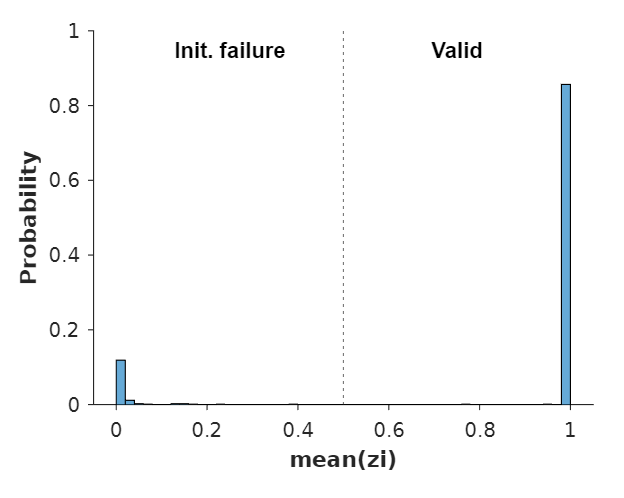

fig_zi = figure(80); clf(80);
set(fig_zi, 'Units', 'Centimeters', 'Position', [1 1 10 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

ax_zi = axes;
set(ax_zi, 'Units', 'Centimeters', 'Position', [1.5 1.5 8 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

histogram(ax_zi, Beh.zi, 'BinWidth', 0.02, 'Normalization', 'probability');
xline(ax_zi, 0.5, 'LineStyle', ':');
xlabel(ax_zi, 'mean(zi)', 'FontWeight', 'bold');
ylabel(ax_zi, 'Probability', 'FontWeight', 'bold');
text(ax_zi, .75, .95, 'Valid', 'FontWeight', 'bold', 'HorizontalAlignment','center');
text(ax_zi, .25, .95, 'Init. failure', 'FontWeight', 'bold', 'HorizontalAlignment','center');
save_name = "Post_zi" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_zi, save_path);

param_names = string(param_names);
param_names = strrep(param_names, " ", "");
ParamPost = array2table(post_sample_param, 'VariableNames', param_names);


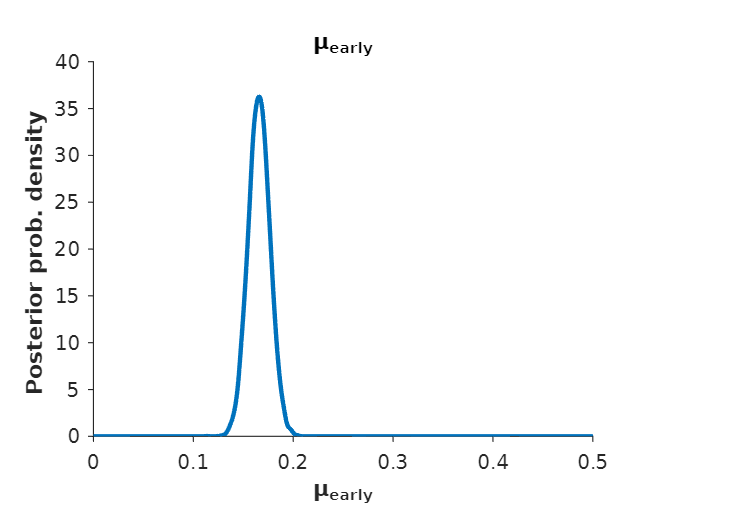


fig_mu_early = figure(81); clf(81);
set(fig_mu_early, 'Units', 'Centimeters', 'Position', [1 1 12 8.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
ax_mu_early = axes;
set(ax_mu_early, 'Units', 'Centimeters', 'Position', [1.5 1.5 8 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

pdf_mu_early = ksdensity(ParamPost.mu_early, 0:.001:.5);
plot(ax_mu_early, 0:.001:.5, pdf_mu_early, 'LineWidth', 2);
xlabel(ax_mu_early, 'μ_{early}', 'FontWeight', 'bold');
ylabel(ax_mu_early, 'Posterior prob. density ', 'FontWeight', 'bold');
title(ax_mu_early, 'μ_{early}', 'FontWeight', 'bold');
save_name = "Post_mu_early_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_mu_early, save_path);

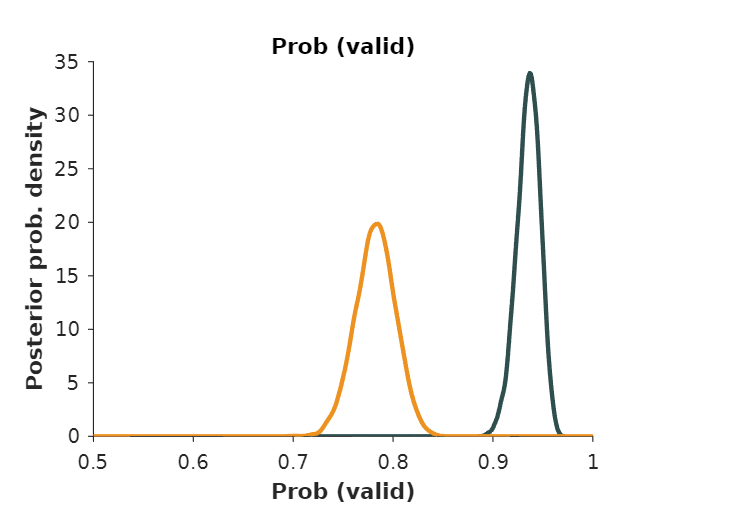

fig_p_chemo_control = figure(82); clf(82);
set(fig_p_chemo_control, 'Units', 'Centimeters', 'Position', [1 1 12 8.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
ax_p_chemo_control = axes;
set(ax_p_chemo_control, 'Units', 'Centimeters', 'Position', [1.5 1.5 8 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

pdf_p_control = ksdensity(ParamPost.p_control, .5:.001:1);
pdf_p_chemo   = ksdensity(ParamPost.p_chemo, .5:.001:1);

plot(ax_p_chemo_control, .5:.001:1, pdf_p_control, 'LineWidth', 2, 'Color', GPSColor.Control);
plot(ax_p_chemo_control, .5:.001:1, pdf_p_chemo, 'LineWidth', 2, 'Color', GPSColor.Treat);


xlabel(ax_p_chemo_control, 'Prob (valid)', 'FontWeight', 'bold');
ylabel(ax_p_chemo_control, 'Posterior prob. density', 'FontWeight', 'bold');
title(ax_p_chemo_control, 'Prob (valid)', 'FontWeight', 'bold');
save_name = "Post_p_chemo_control_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_p_chemo_control, save_path);

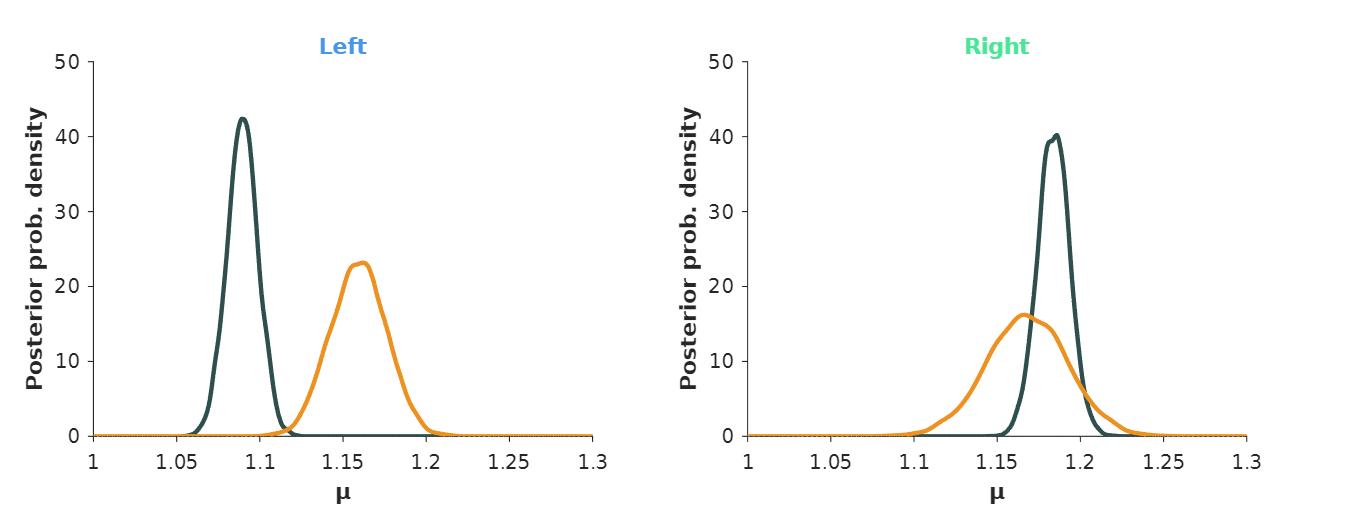

fig_mu_chemo_control = figure(83); clf(83);
set(fig_mu_chemo_control, 'Units', 'Centimeters', 'Position', [1 1 22 8.5], 'PaperPositionMode', 'Auto', 'Color', 'w');

%
ax_mu_chemo_control_l = axes;
set(ax_mu_chemo_control_l, 'Units', 'Centimeters', 'Position', [1.5 1.5 8 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

pdf_mu_control_l = ksdensity(ParamPost.mu_control_l, 1:.001:1.3);
pdf_mu_chemo_l   = ksdensity(ParamPost.mu_chemo_l, 1:.001:1.3);

plot(ax_mu_chemo_control_l, 1:.001:1.3, pdf_mu_control_l, 'LineWidth', 2, 'Color', GPSColor.Control);
plot(ax_mu_chemo_control_l, 1:.001:1.3, pdf_mu_chemo_l, 'LineWidth', 2, 'Color', GPSColor.Treat);

xlim([1 1.3])

xlabel(ax_mu_chemo_control_l, 'μ', 'FontWeight', 'bold');
ylabel(ax_mu_chemo_control_l, 'Posterior prob. density', 'FontWeight', 'bold');
title(ax_mu_chemo_control_l, 'Left', 'FontWeight', 'bold', 'Color', GPSColor.PortL);

%
ax_mu_chemo_control_r = axes;
set(ax_mu_chemo_control_r, 'Units', 'Centimeters', 'Position', [12 1.5 8 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

pdf_mu_control_r = ksdensity(ParamPost.mu_control_r, 1:.001:1.3);
pdf_mu_chemo_r   = ksdensity(ParamPost.mu_chemo_r, 1:.001:1.3);

plot(ax_mu_chemo_control_r, 1:.001:1.3, pdf_mu_control_r, 'LineWidth', 2, 'Color', GPSColor.Control);
plot(ax_mu_chemo_control_r, 1:.001:1.3, pdf_mu_chemo_r, 'LineWidth', 2, 'Color', GPSColor.Treat);

xlim([1 1.3])

xlabel(ax_mu_chemo_control_r, 'μ', 'FontWeight', 'bold');
ylabel(ax_mu_chemo_control_r, 'Posterior prob. density', 'FontWeight', 'bold');
title(ax_mu_chemo_control_r, 'Right', 'FontWeight', 'bold', 'Color', GPSColor.PortR);
save_name = "Post_mu_chemo_control_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_mu_chemo_control, save_path);

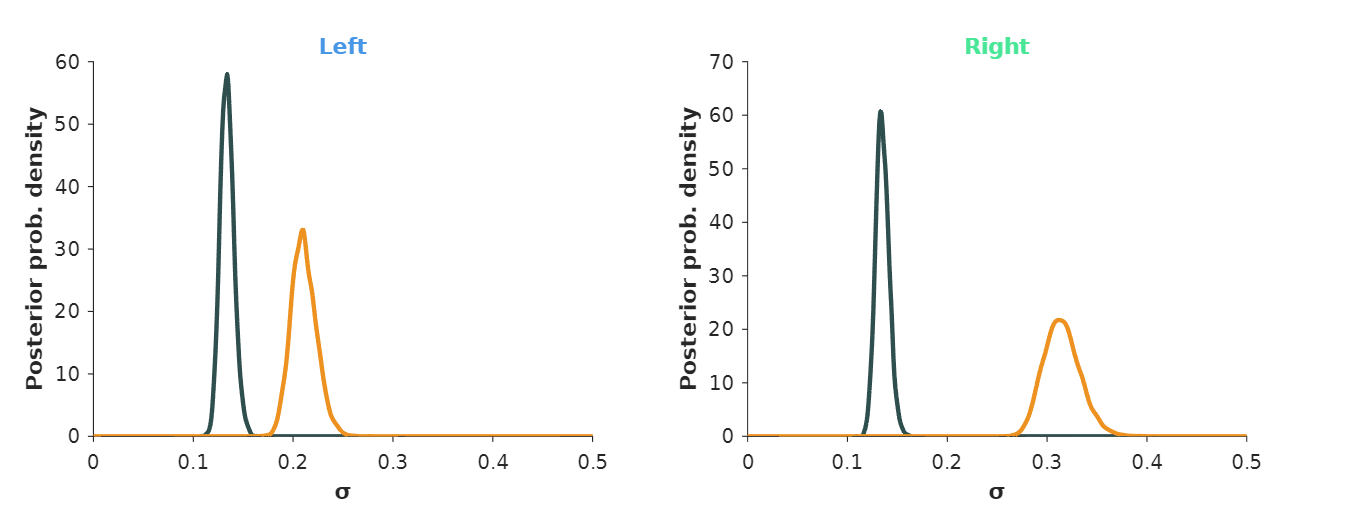

fig_sigma_chemo_control = figure(84); clf(84);
set(fig_sigma_chemo_control, 'Units', 'Centimeters', 'Position', [1 1 22 8.5], 'PaperPositionMode', 'Auto', 'Color', 'w');

%
ax_sigma_chemo_control_l = axes;
set(ax_sigma_chemo_control_l, 'Units', 'Centimeters', 'Position', [1.5 1.5 8 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

pdf_sigma_control_l = ksdensity(ParamPost.sigma_control_l, 0:.001:0.8);
pdf_sigma_chemo_l   = ksdensity(ParamPost.sigma_chemo_l, 0:.001:0.8);

plot(ax_sigma_chemo_control_l, 0:.001:0.8, pdf_sigma_control_l, 'LineWidth', 2, 'Color', GPSColor.Control);
plot(ax_sigma_chemo_control_l, 0:.001:0.8, pdf_sigma_chemo_l, 'LineWidth', 2, 'Color', GPSColor.Treat);

xlim([0 .5])

xlabel(ax_sigma_chemo_control_l, 'σ', 'FontWeight', 'bold');
ylabel(ax_sigma_chemo_control_l, 'Posterior prob. density', 'FontWeight', 'bold');
title(ax_sigma_chemo_control_l, 'Left', 'FontWeight', 'bold', 'Color', GPSColor.PortL);

%
ax_sigma_chemo_control_r = axes;
set(ax_sigma_chemo_control_r, 'Units', 'Centimeters', 'Position', [12 1.5 8 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

pdf_sigma_control_r = ksdensity(ParamPost.sigma_control_r, 0:.001:0.8);
pdf_sigma_chemo_r   = ksdensity(ParamPost.sigma_chemo_r, 0:.001:0.8);

plot(ax_sigma_chemo_control_r, 0:.001:0.8, pdf_sigma_control_r, 'LineWidth', 2, 'Color', GPSColor.Control);
plot(ax_sigma_chemo_control_r, 0:.001:0.8, pdf_sigma_chemo_r, 'LineWidth', 2, 'Color', GPSColor.Treat);

xlim([0 .5])

xlabel(ax_sigma_chemo_control_r, 'σ', 'FontWeight', 'bold');
ylabel(ax_sigma_chemo_control_r, 'Posterior prob. density', 'FontWeight', 'bold');
title(ax_sigma_chemo_control_r, 'Right', 'FontWeight', 'bold', 'Color', GPSColor.PortR);
save_name = "Post_sigma_chemo_control_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_sigma_chemo_control, save_path);

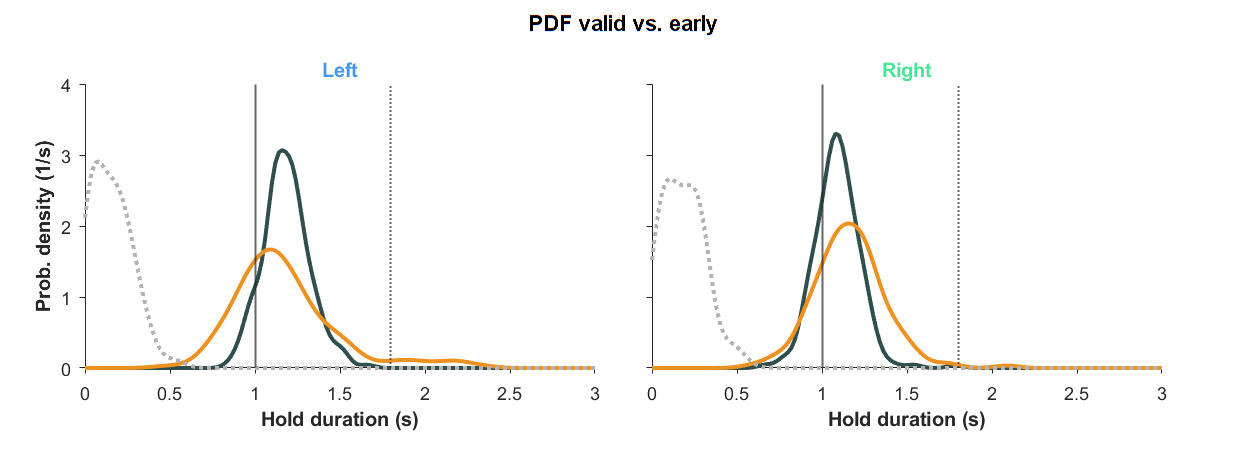

bins = 0:0.02:3;

fig_pdf = figure(71); clf(71);
set(fig_pdf, 'Units', 'Centimeters', 'Position', [1 1 22 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_pdf, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "PDF valid vs. early", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

plot_height = 5;
plot_width  = 9;

%
pdf_valid_control_left = ksdensity(Beh.HoldDuration(Beh.zi > 0.5 & Beh.Label=="Control" & Beh.Cued==0 & Beh.PortCorrect==1), bins);
pdf_valid_chemo_left = ksdensity(Beh.HoldDuration(Beh.zi > 0.5 & Beh.Label=="Chemo" & Beh.Cued==0 & Beh.PortCorrect==1), bins);
pdf_early_left = ksdensity(Beh.HoldDuration(Beh.zi < 0.5 & Beh.Cued==0 & Beh.PortCorrect==1), bins);

ax_pdf_l = axes;
set(ax_pdf_l, 'Units', 'Centimeters', 'Position', [1.5 1.5 plot_width plot_height], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
plot(ax_pdf_l, bins, pdf_valid_control_left, "Color", GPSColor.Control, 'LineWidth', 2);
plot(ax_pdf_l, bins, pdf_valid_chemo_left, "Color", GPSColor.Treat, 'LineWidth', 2);
plot(ax_pdf_l, bins, pdf_early_left, "Color", [.7 .7 .7], 'LineWidth', 2, 'LineStyle', ':');

xline(ax_pdf_l, 1, 'LineWidth', 1);
xline(ax_pdf_l, 1.8, 'LineWidth', 1, 'LineStyle', ':');

title(ax_pdf_l, 'Left', 'FontWeight', 'bold', 'Color', GPSColor.PortL);
ylabel(ax_pdf_l, 'Prob. density (1/s)', 'FontWeight', 'bold');
xlabel(ax_pdf_l, 'Hold duration (s)', 'FontWeight', 'bold');

%
pdf_valid_control_right = ksdensity(Beh.HoldDuration(Beh.zi > 0.5 & Beh.Label=="Control" & Beh.Cued==0 & Beh.PortCorrect==2), bins);
pdf_valid_chemo_right = ksdensity(Beh.HoldDuration(Beh.zi > 0.5 & Beh.Label=="Chemo" & Beh.Cued==0 & Beh.PortCorrect==2), bins);
pdf_early_right = ksdensity(Beh.HoldDuration(Beh.zi < 0.5 & Beh.Cued==0 & Beh.PortCorrect==2), bins);

ax_pdf_r = axes;
set(ax_pdf_r, 'Units', 'Centimeters', 'Position', [1.5+plot_width+1 1.5 plot_width plot_height], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
plot(ax_pdf_r, bins, pdf_valid_control_right, "Color", GPSColor.Control, 'LineWidth', 2);
plot(ax_pdf_r, bins, pdf_valid_chemo_right, "Color", GPSColor.Treat, 'LineWidth', 2);
plot(ax_pdf_r, bins, pdf_early_right, "Color", [.7 .7 .7], 'LineWidth', 2, 'LineStyle', ':');

xline(ax_pdf_r, 1, 'LineWidth', 1);
xline(ax_pdf_r, 1.8, 'LineWidth', 1, 'LineStyle', ':');

title(ax_pdf_r, 'Right', 'FontWeight', 'bold', 'Color', GPSColor.PortR);
yticklabels(ax_pdf_r, []);
xlabel(ax_pdf_r, 'Hold duration (s)', 'FontWeight', 'bold');

ax_pdf_l.YLim(2) = max([ax_pdf_l.YLim(2) ax_pdf_r.YLim(2)]);
ax_pdf_r.YLim(2) = ax_pdf_l.YLim(2);

save_name = "PDF_early_valid_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_pdf, save_path);

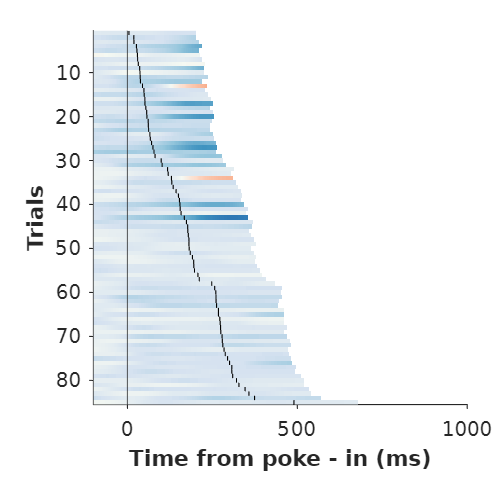

mycolormap = customcolormap_preset('red-white-blue');

fig_init_fail = figure(80); clf(80);
set(fig_init_fail, 'Units', 'Centimeters', 'Position', [1 1 8 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

ax_init_fail = axes;
set(ax_init_fail, 'Units', 'Centimeters', 'Position', [1.5 1.5 6 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YDir', 'reverse');

colormap(mycolormap);

id_init_fail = find(obj.TrialInfo.zi<.5);

hd_this = obj.HD(id_init_fail);

[hd_sorted, id_sort] = sort(hd_this);
traj_sorted = obj.AngleHeadMatIn(id_init_fail(id_sort), :);

imagesc(ax_init_fail, traj_sorted, "AlphaData", ~isnan(traj_sorted))

for i = 1:length(hd_sorted)
    out_time = 100 + 1000 * hd_sorted(i);
    plot(ax_init_fail, [out_time out_time], i+[-.5 .5], '-k', 'LineWidth', .5);
end

xline(ax_init_fail, 100)

xlim(ax_init_fail, [0 1100])
ylim(ax_init_fail, .5+[0 length(id_init_fail)])
clim(ax_init_fail, [-90 90])
xticks(ax_init_fail, 100:500:3100);
xticklabels(ax_init_fail, {'0', '500', '1000', '1500', '2000', '2500', '3000'});
xlabel(ax_init_fail, 'Time from poke - in (ms)', 'FontWeight', 'bold');
ylabel(ax_init_fail, 'Trials', 'FontWeight', 'bold');

save_name = "traj_init_fail_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_init_fail, save_path);

% obj.TrialInfo = addvars(obj.TrialInfo, zi_Traj, 'NewVariableNames', "zi");
% obj.save(TaskDir)